# 2.3.3 采样及零阶保持

## 一周期信号$e_1 \left(t\right)=\mathrm{sin}\left(2\pi t\right)$用采样频率10Hz进行周期采样，后通过零阶保持器，试画出

## a 周期信号$e_1 \left(t\right)=\sin \left(2\pi t\right)$的幅值谱；

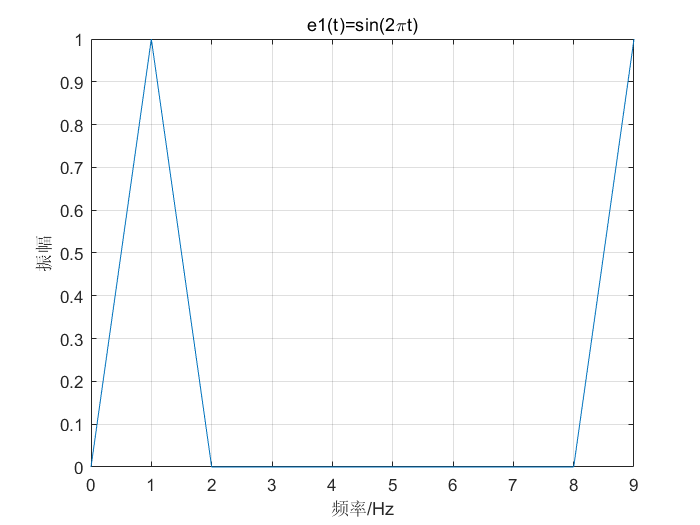

fs = 10; %采样频率为10Hz
t = 0:1/fs:0.9; %采样时间为一个周期
e1 = sin(2*pi*t); %信号
N = size(e1,2); %数据点数 2对应矩阵的列数->10
y1 = fft(e1,N); %信号的快速傅里叶变换
f1 = (0:N-1)*fs/N; %频率序列
mag1 = abs(y1)*2/N; %求取幅值 abs()计算幅值 求取Fourier变换的振幅,其中*2/N转变为真实幅值
plot(f1,mag1);
xlabel('频率/Hz');
ylabel('振幅');
grid on;
title('e1(t)=sin(2\pit)'); %绘出幅频图

① **fft(X,N) **is the N-point fft, padded with zeros if X has less than N points and  truncated if it has more.

X：采样过后的信号  N：采样点数量

fft()函数输出的结果为每个采样点对应的幅值，第一个值对应的是直流分量的振幅，第二个值对应第一个采样点，第三个值对应第二个采样点...第n个值对应第n-1个采样点

y1 = fft(e1,N); %信号的快速傅里叶变换

② 求取真实幅值时，需要在fft()函数输出幅值的基础上进行$\times 2\div N$的运算

$\times 2$原因如下：

现有一周期函数的傅里叶级数$f\left(t\right)=c_0 +c_1 \mathrm{cos}\left(\omega_1 t+\varphi_1 \right)+c_2 \mathrm{cos}\left({2\omega }_1 t+\varphi_2 \right)=F_0 +F_{-1} e^{j\omega_1 t} {+F}_1 e^{j\omega_1 t} +F_{-2} e^{-\mathrm{j2}\omega_1 t} +F_{-2} e^{\mathrm{j2}\omega_1 t}$

函数相应的分量幅度：$F_0 =c_0$、$F_1 =\frac{c_1 }{2}e^{j\varphi_1 }$、$F_{-1} =\frac{c_1 }{2}e^{-j\varphi_1 }$、$F_2 =\frac{c_2 }{2}e^{j\varphi_2 }$、$F_{-2} =\frac{c_2 }{2}e^{-j\varphi_2 }$

$\div N$原因如下：

由Fourier变换对

$X\left(k\right)=\sum_{j=1}^N x\left(j\right)\omega_N^{\left(j-1\right)\left(k-1\right)}$  ==>  $x\left(j\right)=\frac{1}{N}\sum_{k=1}^N X\left(k\right)\omega_N^{-\left(j-1\right)\left(k-1\right)}$  where  $\omega_N =e^{\frac{\left(-2\pi i\right)}{N}}$

可知fft()函数直接结算得到的$X\left(k\right)$并不是频谱幅值

在$x\left(j\right)$的Fourier级数中，谐波分量$\omega_N =e^{\frac{\left(-2\pi i\right)}{N}}$对应的幅值为$\frac{X\left(k\right)}{N}$

mag1 = abs(y1)*2/N; %求取幅值 abs()计算幅值 求取Fourier变换的振幅,其中*2/N转变为真实幅值

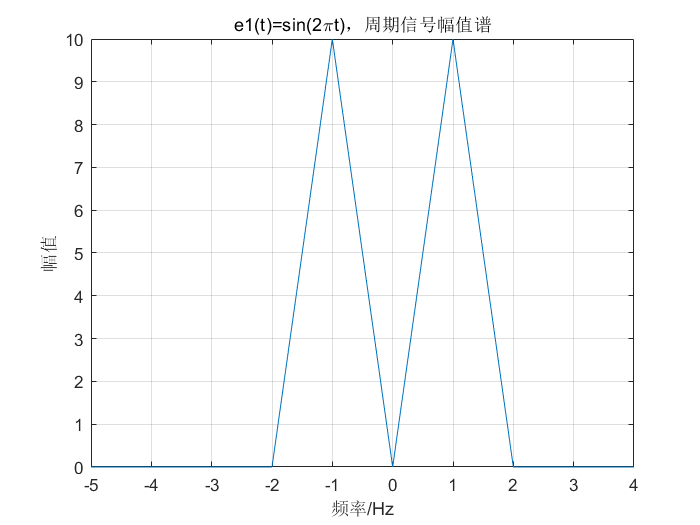

y2 = fftshift(y1); %将fft结果以fs/2为中心左右互换 将零频点移到频谱中间
f2 = (0:N-1)*fs/N-fs/2; %将真实频率减去fs/2
mag2 = abs(y2)*2/N*fs; %乘1/T
plot(f2,mag2);
xlabel('频率/Hz');
ylabel('幅值');
grid on;
title('e1(t)=sin(2\pit)，周期信号幅值谱')

① 为什么要使用fftshift()函数？

因为实信号以fs为采样速率的信号在 s/2处混叠，所以实信号fft()的结果中前半部分对应[0,fs/2],后半部分对应[-fs/2, 0]

大于fs/2的部分的频谱实际上是实信号的负频率加fs的结果

故要得到正确的结果，只需将视在频率减去fs即可得到频谱对应的真实负频率

如果要让实信号fft的结果与[-fs/2, fs/2]对应，则要fft()后fftshift()一下即可

y2 = fftshift(y1); %将fft结果以fs/2为中心左右互换 将零频点移到频谱中间

② 为什么在原有幅值的基础上再乘以1/T？

原因见下图推导：

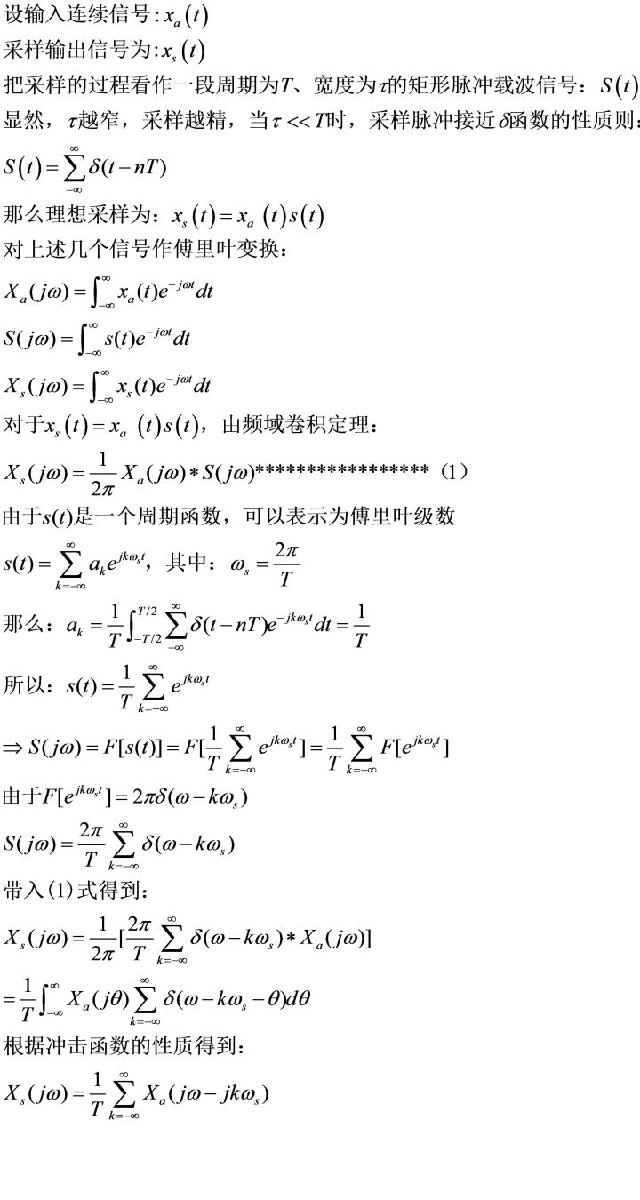

mag2 = abs(y2)*2/N*fs; %乘1/T

## b 周期信号$e_1 \left(t\right)=\sin \left(2\pi t\right)$被周期采样后，离散信号的幅值谱；（注意离散信号频谱的幅值）

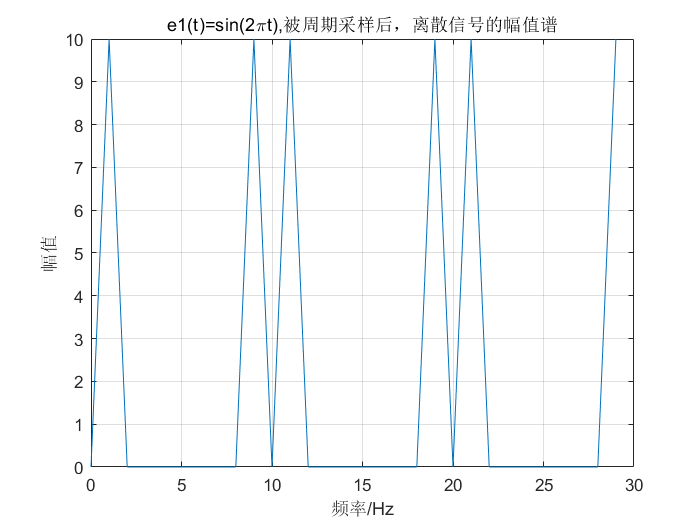

y3 = [abs(y1),abs(y1),abs(y1)]*fs; %周期延拓至0：1：29 乘1/T
mag3 = y3*2/N;
plot(0:1:29,mag3);
xlabel('频率/Hz');
ylabel('幅值');
grid on;
title('e1(t)=sin(2\pit),被周期采样后，离散信号的幅值谱')

① 周期延拓：

每一个abs(y1)都代表一个周期的振幅值，每个周期的采样点对应的幅值情况相同

因此将一个周期的采样点复制成三份延拓成一个由三个周期采样点组成的采样集

y3 = [abs(y1),abs(y1),abs(y1)]*fs; %周期延拓至0：1：29 乘1/T

② 奈奎斯特采样频率：

系统的频率为1Hz，根据奈奎斯特采样频率公式可得$f_N >2\mathrm{Hz}$,根据仿真图像也可得出此结论，两者一致。